# Textra-01. Defining a window in time domain

## Introduction

In this tutorial you will learn how to obtain a window in time domain. A window can be applied to data, either time series (data window) of covariance functions (lag window), before computing their DTFT. 

Different windows provide different trade-offs between resolution and leakage obtained in the frequency domain. To check these trade-offs, see tutorial '*Textra_02_analysing_resolution_leakage_tradeoff*'.

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters
window_type = 'data_window';    % 'data_window' for time series
                                % 'lag_window' for covariance functions

N_window    = 30;               % number of elements 
                                % must be even for data_window
                                % must be odd for lag_window

window_name_list = {'rectangular',...
                    'triangular',...
                    'Hann',...
                    'Hamming',...
                    'Nuttall',...               
                    'Truncated_Gaussian',...    
                    'Chebyshev'};               

alpha_vector = linspace(1,5,5);    % Values of alpha parameter 
                                   % for Truncated Gaussian window


%%% Plot parameters
font_size       = 18;
line_width      = 2;

Initialise a window object with the fields required by function `get_window`.

window0 = initialise_window('type',window_type,...
                            'N',N_window);

Get a triangular window and plot it. For a list of available window names, see function `initialise_window`.

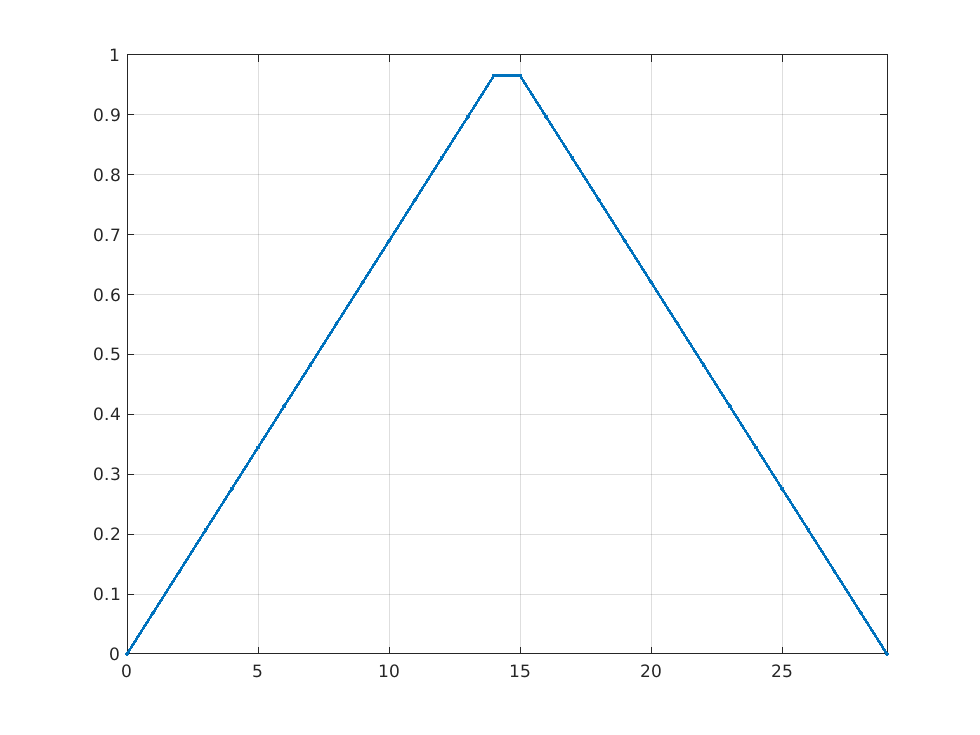

window_triangular          = window0;
window_triangular.name     = 'triangular';

window_triangular = get_window(window_triangular);

figure

x = window_triangular.x_values;
y = window_triangular.y_values;
plot(x,y,'.-','LineWidth',line_width)
xlim([x(1) x(end)])
grid on

Get all the windows included in `window_name_list`, and plot them.

figure

for ii = 1:numel(window_name_list)

    window_local        = window0;    
    window_local.name   = window_name_list{ii};
    window_local        = get_window(window_local);

    x = window_local.x_values;
    y = window_local.y_values;    
    plot(x,y,'.-','LineWidth',line_width)

    hold on

end

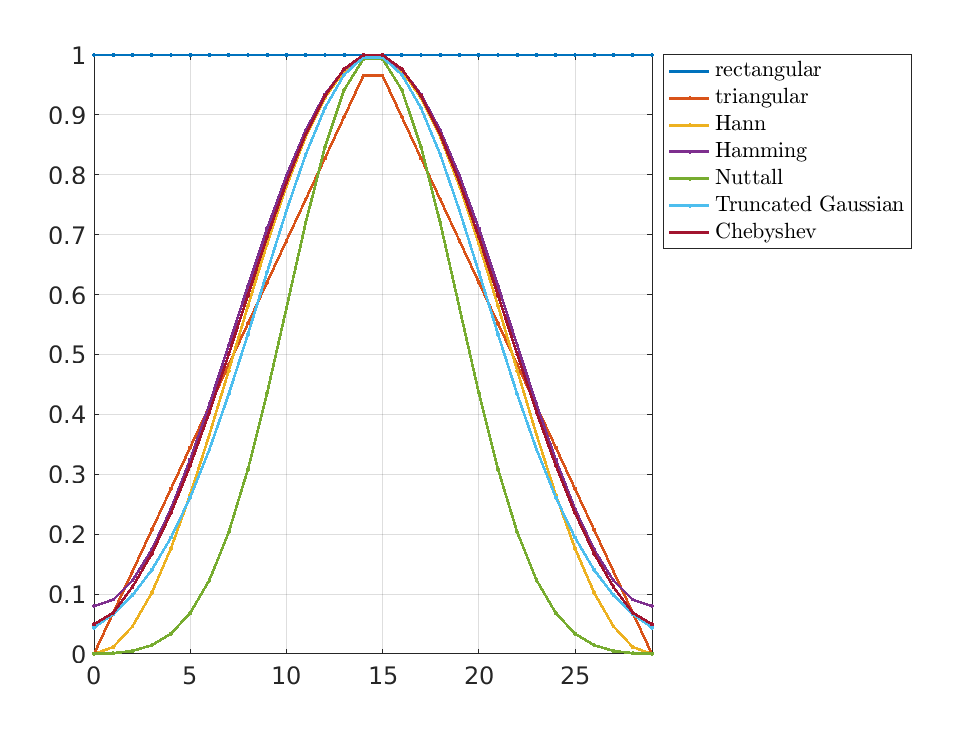


xlim([x(1) x(end)])
window_name_list_fancy = strrep(window_name_list,'_',' ');    
legend(window_name_list_fancy,'Interpreter','latex','location','bestoutside')
grid on
set(gca,'fontsize',font_size)

Note the obtained warnings. This is because, for some windows, additional parameters are required. If not provided, default values are internally taken from function `fun_default_values.`

For example, Truncated Gaussian depends on parameter `alpha`. Get different Truncated Gaussian windows for different parameter values.

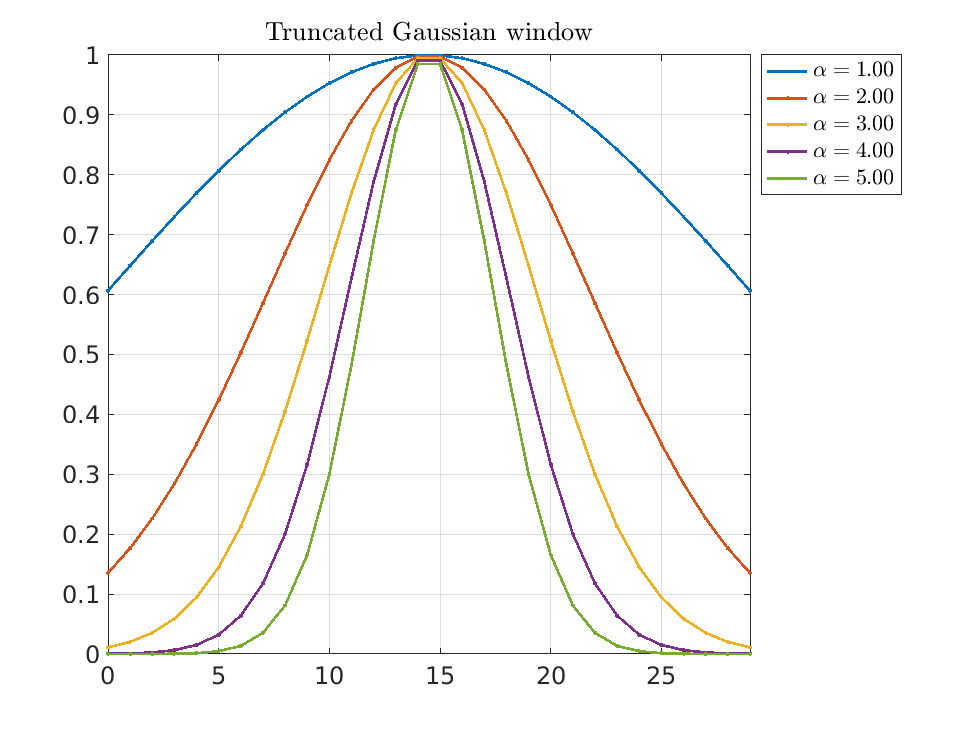

figure

for jj = 1:numel(alpha_vector)

    % define the parameter value
    alpha = alpha_vector(jj);

    % define the substructure 'y_parameters' for window object
    y_parameters.alpha = alpha;

    % initialise window with substructure y_parameters
    % (alternatively, just plug 'y_parameters' into an existing window)
    window_alpha = initialise_window('type',window_type,...
                                     'name','Truncated_Gaussian',...
                                     'N',N_window,...
                                     'y_parameters',y_parameters);
    
    window_alpha        = get_window(window_alpha);

    x = window_alpha.x_values;
    y = window_alpha.y_values;    
    plot(x,y,'.-','LineWidth',line_width)

    hold on

end

title('Truncated Gaussian window','Interpreter','latex')
xlim([x(1) x(end)])
alpha_vector_fancy = strcat('$\alpha =',sprintfc('%.2f',alpha_vector));
alpha_vector_fancy = strcat(alpha_vector_fancy,'$');
legend(alpha_vector_fancy ,'Interpreter','latex','location','bestoutside')
grid on
set(gca,'fontsize',font_size)

## Remarks

- Note that windows applied to time seres (data windows) range from $x[0]$ to $x[N-1]$, where $N$ is the data length, while windows applied to covariance functions range from $x[-M]$ to $x[M]$, where $M$ is the maximum lag of the covariance function. Thus, in the latter case it holds that $N=2 \cdot M+1$. You can explore both window types by changing the parameter `window_type`.